# Comparison of local relative rate obtained from standard DTW vs. FDA-based methods

This script examines whether methods that perform an initial linear time normalization before a non-linear time normalization, such as FDA-based approaches, will obtain relative rate time-series that match ground truth relative rates.

For the FDA-based approach, we use J. Lucero's TrajAlign:

- Lucero, J., Munhall, K., Gracco, V., & Ramsay, J. (1997), "On the registration of time and the patterning of speech movements", JSLHR, 40, pp. 1111-1117.

Note that we edited Lucero's code (see `ComputeFDA_mod.m`) to return the warping functions, which describe how each trajectory is warped to the mean trajectory (which is calculated after the initial linear time normalization).

#### Getting started

To run this livescript, you must have the DTWm and LRR_DTW repositories, available from [https://github.com/tilsen](https://github.com/tilsen)

Follow the instructions in the README file of the repository before running this script. 

%REQUIRED: this script should be run with its parent directory 
% and all of the parent's subdirectories on your path:
addpath(genpath('..')) 

%REQUIRED: the toolbox DTWm (https://github.com/tilsen/DTWm.git)
if ~contains(path,'DTWm')
    fprintf('toolbox DTWm required\n'); return;
end

#### Example signals

Here are three example signals generated from a logistic growth process, described by the differential equation:

    
$$\frac{dx_i(t)}{dt}=\left(g_i+w(t)\right)\cdot x_i(t)\cdot\left(1-\frac{x_i(t)}{L}\right)$$


where:

    
$$w(t)=\alpha_ie^{-t\beta}$$


The term $(g_i+w(t))$ is a time-varying growth rate. It has a constant component $g_i$ that differs among processes (indexed by $i$), and also a time-varying component $w(t)$ which decays or grows exponentially depending on the sign of $\alpha_i$. The parameter $\beta$ governs how quickly this time-varying component changes.

Generate the signals and obtain the ground truth instantaneous rates:

L = 1;                  % logistic growth limit
endval = 0.95;  % endpoint value of signals
x0 = 0.1;          % initial value
dt = 1e-3;          % time step
g = [2 2 3];        % constant component of growth rates
t = 0:dt:10;       % time vector

alpha = [0 1 -2]; % amplitude of time-varying nonlinear perturbation of growth rate
beta = 1; %timescale of nonlinear perturbation

N = numel(g); %number of signals

X={}; T={}; R={}; W={};
for i=1:N

    w = alpha(i)*exp(-t*beta);		% time-varying nonlinear perurbation of growth rates
    growth_rate = g(i)+w;

    x = zeros(1,length(t));
    x(1) = x0;
    for j=2:length(t)
        dx =  growth_rate(j-1)*x(j-1)*(1-x(j-1)/L);
        x(j) = x(j-1) + dx*dt;
    end

    ix_end = find(x>=endval,1,'first');

    X{i} = x(1:ix_end); %signals
    T{i} = t(1:ix_end);   %time  vectors
    r = gradient(x)/dt; %instantaneous signal change rates
    R{i} = r(1:ix_end); 
    W{i} = w(1:ix_end); %time-varying nonlinear perturbations of rate

end

Plot the signals and change rates

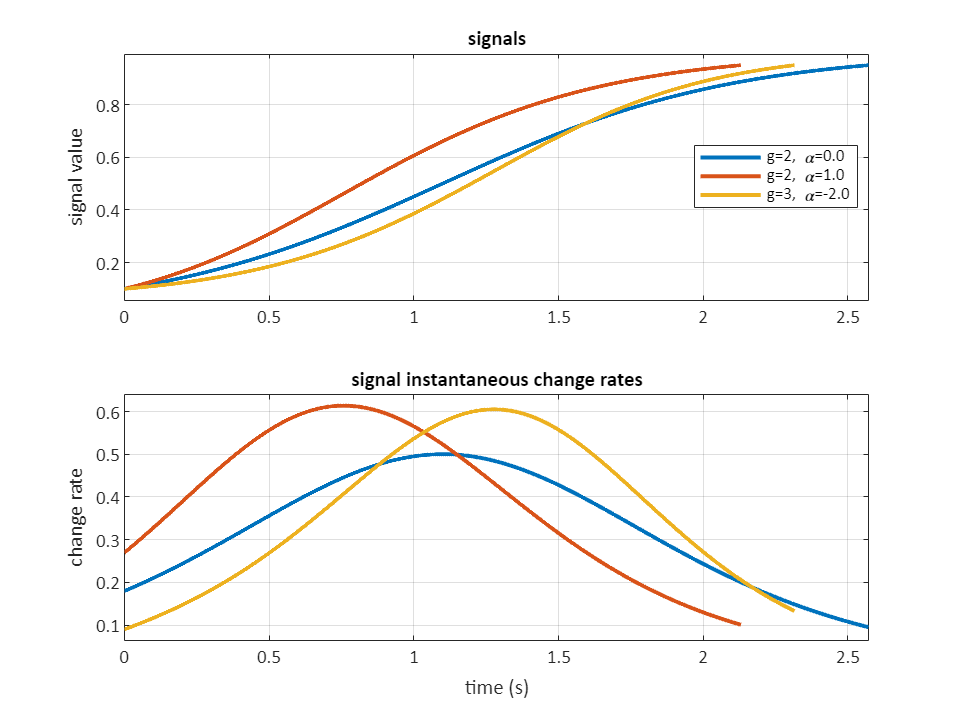

[ax,ph] = plot_signals(T,X,R);
title(ax(1),'signals'); title(ax(2),'signal instantaneous change rates');
ylabel(ax(1),'signal value'); ylabel(ax(2),'change rate');  xlabel('time (s)');
siglabs = arrayfun(@(c,d){sprintf('g=%1.0f, \\alpha=%1.1f',c,d)},g,alpha);
legend(ph(1,:),siglabs,'Location','best');

#### Known (ground truth) relative rate

The ground truth local relative rate for any two monotonic functions is the ratio of the instantaneous change rates, where one signal is taken as a comparison and the other as a target.

However, the definition of the ground truth relative rate is not as simple as taking a ratio of these rates, since the rate timeseries are of different lengths. Thus they have to be matched in an appropriate way. This can be acheived with an asymmetric alignment, using the the DTW warping curve. 

Thus the known relative rate is the ratio of the instantaneous change rate of the target $R_t$ to the instantaneous change rate of the comparison $R_c$, after the comparison $R_c$ is aligned to the target $R_t$, using the DTW mapping of the target signal and comparison signals asymmetrically (such that the time coordinate of the target is adopted):

maps = dtwm_pairwise(X); %warping functions

rel_R={};
for a=1:N
    for b=1:N
        [~,~,map_comp] = align_signals(maps{a,b},X{a},X{b},'aligntype','reference');
        rel_R{a,b} =R{a}./ R{b}(map_comp(2,:));  %ratio of instantaneous change rates
        rel_W{a,b} = W{a}./W{b}(map_comp(2,:)); %ratio of nonlinear components of growth rate
    end
end

Plot the known relative rates

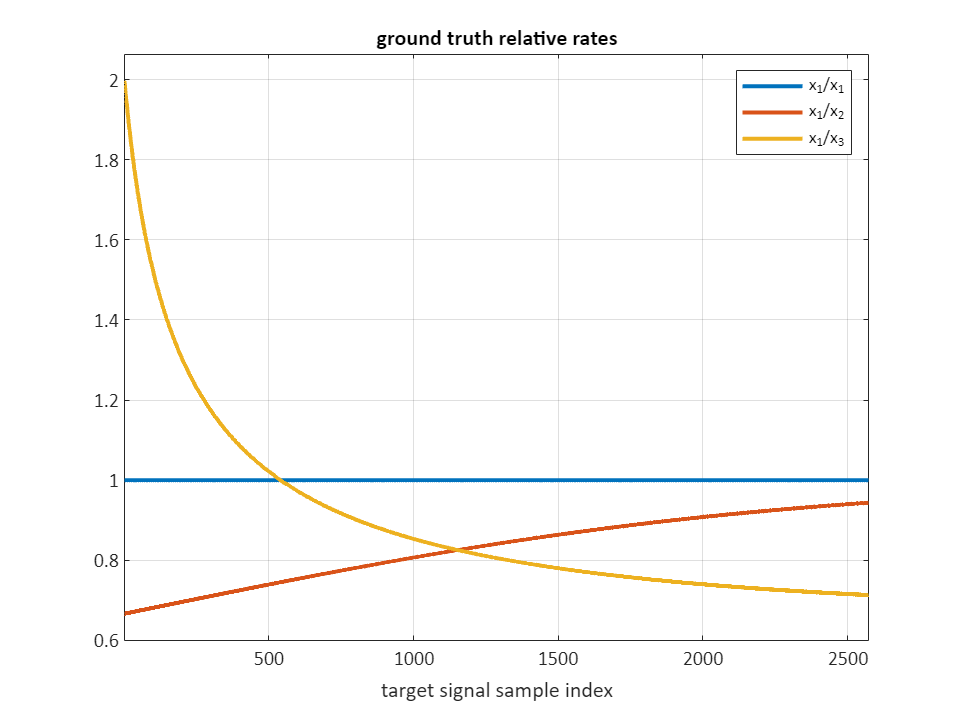

targix =1; %select one signal as the target
[ax,ph] = plot_signals([],rel_R(targix,:));
title(ax,'ground truth relative rates');  xlabel('target signal sample index');
legend(ph,arrayfun(@(c){sprintf('x_{%d}/x_%d',targix,c)},1:3),'location','best');

#### standard DTW-based local relative rate

Calculate the LRR pairwise between signals:

LRR_dtw = lrr_pairwise(X);

Compare the DTW-based and ground truth relative rates:

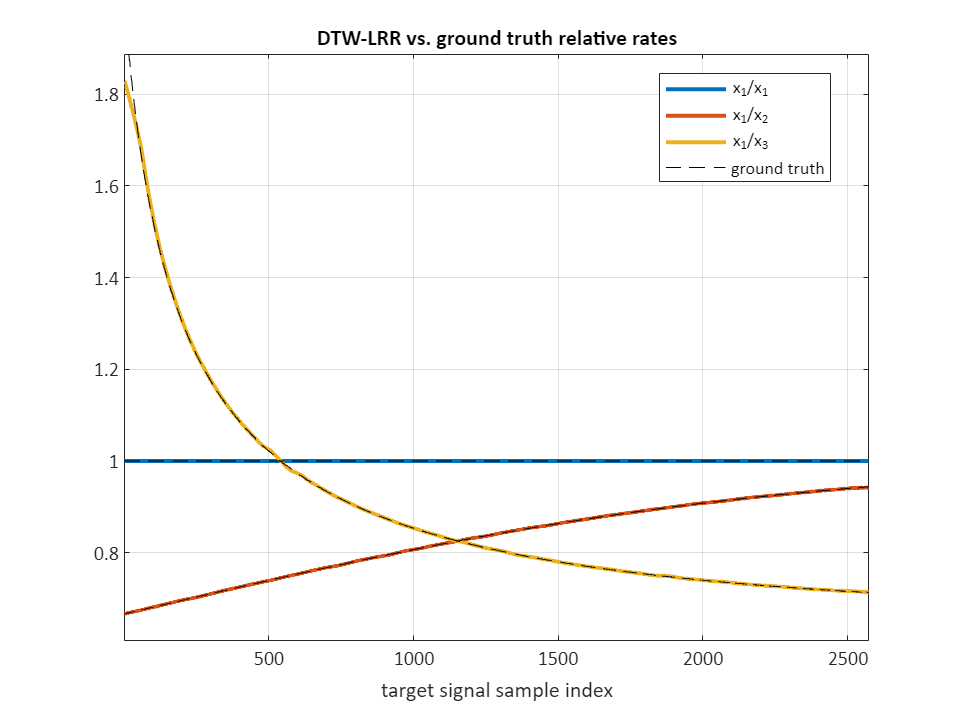

[ax,ph] = plot_signals([],LRR_dtw(targix,:));
for i=1:N, ph(end+1) = plot(rel_R{targix,i},'k--'); end
title(ax,'DTW-LRR vs. ground truth relative rates');  xlabel('target signal sample index');
legend(ph(1:N+1),[arrayfun(@(c){sprintf('x_{%d}/x_%d',targix,c)},1:3) {'ground truth'}],'location','best');

The DTW-LRR of the target signal to each of the comparisons closely matches the empirically calculated ground truths. The deviations near the beginning and ends are edge-effects due to the necessity of using a window to calculate the local slope:.

#### FDA-based local relative rate

Obtain the warping functions and linear warping factors. Note that lambda is a parameter that specifies a roughness penalty for the warping function:

Xtr = cellfun(@(c){c'},X); %transpose signals in cell array

[~,fda_nldtw,~,~,~,~,warping_fcns,lin_wf] = ComputeFDA_mod(Xtr,'LAMBDA',.01);

The warping functions are normalized mappings from signal time indices to indices of the sample mean trajectory, which is obtained from the linearly time-warped signals.

In order to obtain pairwise local relative rates, we can use the ratios of the warping functions, since:

        
$$\frac{\left(\frac{\Delta_i}{\Delta_{\mu}}\right)}{\left(\frac{\Delta_j}{\Delta_{\mu}}\right)}=\frac{\Delta_i}{\Delta_j}$$


The LRR is the reciprocal of the local slope, so $\text{LRR}_{\text{FDA}}=\frac{\Delta_j}{\Delta_i}$

for a=1:N
    for b=1:N
            LRR_fda{a,b} = 1./(warping_fcns(:,a)./warping_fcns(:,b));        
    end
end

Compare the FDA-based and ground truth relative rates:

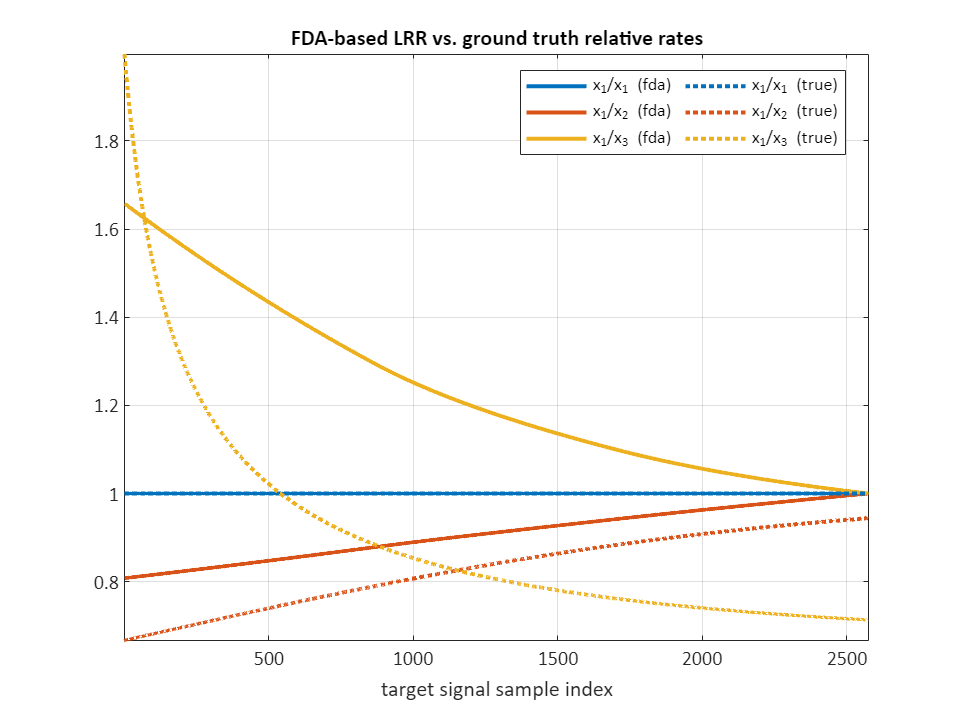

[ax,ph] = plot_signals([],LRR_fda(targix,:));
colors = lines(N);
for i=1:N, ph(end+1) = plot(rel_R{targix,i},':','color',colors(i,:),'linew',2); end
axis(ax,'tight');
title(ax,'FDA-based LRR vs. ground truth relative rates');  xlabel('target signal sample index');
legstrs = [arrayfun(@(c){sprintf('x_{%d}/x_%d (fda)',targix,c)},1:3) ...
    arrayfun(@(c){sprintf('x_{%d}/x_%d (true)',targix,c)},1:3)];
legend(ph,legstrs,'location','best','NumColumns',2);

Notice that the relative rates obtained from the FDA warping functions do not match the ground truth rates.

#### Can the warping functions be adjusted to give the correct local relative rates?

Perhaps it is possible that the warping associated with the first step of linear normalization can be used to reconstruct the ground truth relative rates from the FDA-based relative rates. If the effects of the linear and nonlinear timewarping on the relative rates could be composed, then we might expect the following:

$LRR_{\text{sDTW}}(x,y)=LRR_{\text{FDA}}\left(\text{LTW}(x,y)\right)=LRR(x_{ltw},y_{ltw})\cdot\text{W(x,y)$,

meaning that the standard DTW-based local relative rate would be equivalent to the product of the FDA-based local relative rate of linearly time warped signals $x$ and $y$ and the linear component of relative rate, $W(x,y)$, calculated as the ratio of the linear warping factors. However, this is not the case:

for a=1:N
    for b=1:N
        LRR_fda_adj{a,b} = LRR_fda{a,b}*lin_wf(a)/lin_wf(b);
    end
end

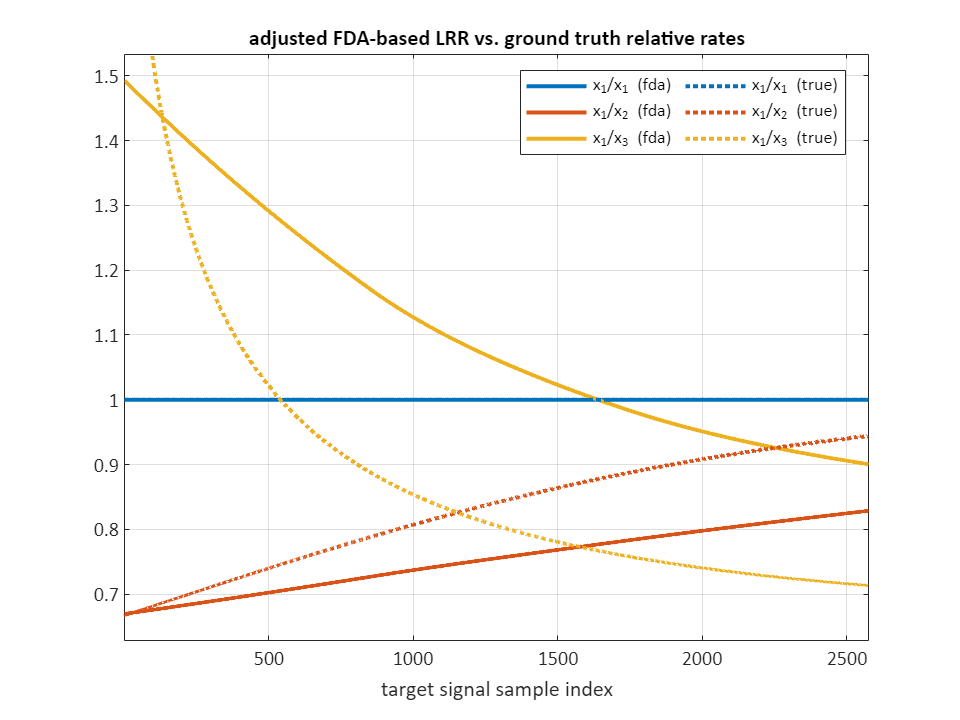

[ax,ph] = plot_signals([],LRR_fda_adj(targix,:));
colors = lines(N);
for i=1:N, ph(end+1) = plot(rel_R{targix,i},':','color',colors(i,:),'linew',2); end
title(ax,'adjusted FDA-based LRR vs. ground truth relative rates');  xlabel('target signal sample index');
legstrs = [arrayfun(@(c){sprintf('x_{%d}/x_%d (fda)',targix,c)},1:3) ...
    arrayfun(@(c){sprintf('x_{%d}/x_%d (true)',targix,c)},1:3)];
legend(ph,legstrs,'location','best','NumColumns',2);

It is possible that there exists some more complicated adjustment of the FDA-based warping functions that can allow them to be used to construct the relative rate, but we are not aware of what that adjustment would be.

#### Are nonlinear and linear warpings composable with respect to the warping function?

Above we showed that FDA-based warping functions will not provide correct local relative rates. Here we repeat the demonstration but solely using standard DTW:

Say we perform a linear warping first, and then standard DTW:

med_len = median(cellfun('length',X));
for i=1:numel(X)
    X_linnorm{i} = interp1(1:length(X{i}),X{i},linspace(1,length(X{i}),med_len));
end

LRRs_ln = lrr_pairwise(X_linnorm);

The local relative rates obtained when applying linear time normalization before standard DTW do not correspond to the ground truth relative rates. It is also evident from below that the LRRs in this case cannot be transformed to the correct relative rates simply by multiplying the linear warping factors.

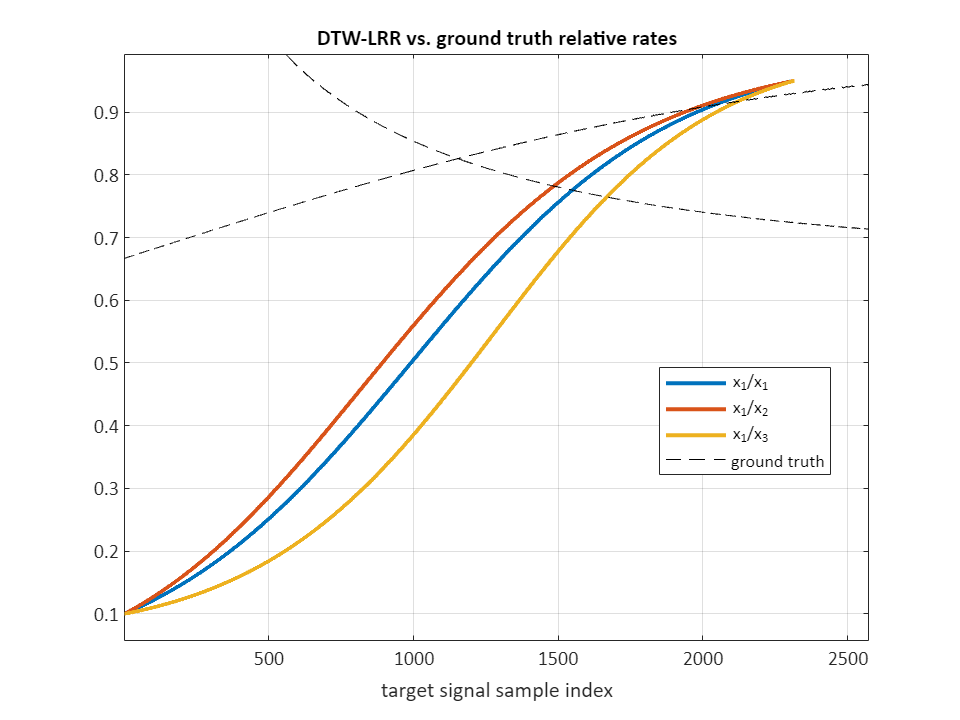

[ax,ph] = plot_signals([],X_linnorm(targix,:));
for i=1:N, ph(end+1) = plot(rel_R{targix,i},'k--'); end
title(ax,'DTW-LRR vs. ground truth relative rates');  xlabel('target signal sample index');
legend(ph(1:N+1),[arrayfun(@(c){sprintf('x_{%d}/x_%d',targix,c)},1:3) {'ground truth'}],'location','best');

function [h] = figls()
h = figure('units','pixels','position',[0 0 640 480]);
end

function [ax,ph] = plot_signals(T,varargin)
h = figls;
P = numel(varargin);
for i=1:P
    ax(i) = subplot(P,1,i);
    X = varargin{i};
    N = numel(X);
    colors = lines(N);
    for j=1:N
        if isempty(T)
            ph(i,j) = plot(X{j},'linew',2,'color',colors(j,:)); hold on;
        else
            ph(i,j) = plot(T{j},X{j},'linew',2,'color',colors(j,:)); hold on;
        end
    end
    axis tight;
    ylim(ylim+0.05*diff(ylim)*[-1 1]);
    set(gca,'xgrid','on','ygrid','on');
end

end